BME 3053C Final Project

Author: Manuel Cortes

Group Members: Samantha Kirse, Jash Patel

Course: BME 3053C Computer Applications for BME

Term: Spring2021

J. Crayton Pruitt Family Department of Biomedical Engineering

University of Florida

Email: manuel.cortes@ufl.edu

February 24, 2021

data = readtable("heart.csv")

data = 303×14 table
    age    sex    cp    trestbps    chol    fbs    restecg    thalach    exang    oldpeak    slope    ca    thal    target
    ___    ___    __    ________    ____    ___    _______    _______    _____    _______    _____    __    ____    ______

    63      1     3       145       233      1        0         150        0        2.3        0      0      1        1   
    37      1     2       130       250      0        1         187        0        3.5        0      0      2        1   
    41     

age = data.age;
BPrest = data.trestbps;
maxHR = data.thalach;

dataset = [data.sex BPrest maxHR data.oldpeak data.chol data.fbs data.exang data.age data.slope] ; 

Descriptive Statistics

datamatrix = table2array(data); %Converts the table to a matrix
DataMean = mean(datamatrix); %finds the mean of the matrix values 
standardDev = std(datamatrix); %finds the standard deviation of the matrix values
Attributes = ["Age"; "Chest Pain"; "Blood Pressure"; "Cholestoral"; "Heart Rate"]; %these are the values we will gather statistics on
Mean = [DataMean(1); DataMean(3); DataMean(4); DataMean(5); DataMean(8)];          %it does not make sense to find statistics about the ohter values such as 'sex'
Standard_Deviation = [standardDev(1); standardDev(3); standardDev(4); standardDev(5); standardDev(8)];
Descriptive_Statistics = table(Attributes, Mean , Standard_Deviation) %tabulates the mean and standard deviation of specific data values. 

Descriptive_Statistics = 5×3 table
       Attributes        Mean     Standard_Deviation
    ________________    ______    __________________

    "Age"               54.366          9.0821      
    "Chest Pain"         0.967          1.0321      
    "Blood Pressure"    131.62          17.538      
    "Cholestoral"       246.26          51.831      
    "Heart Rate"        149.65          22.905      


Visualization

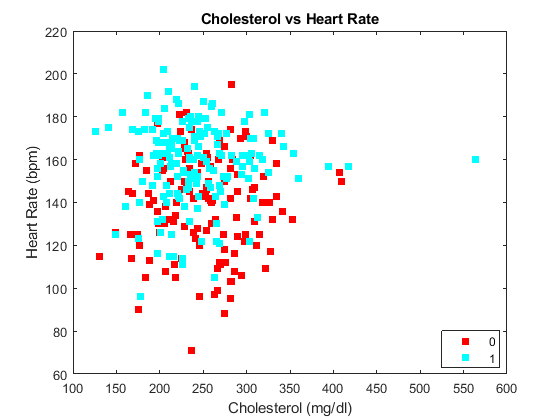

figure(1)
gscatter(age, BPrest, data.target); %Graphs age and blood pressure against the target (presence of heart disease) in the individuals from the dataset
title("Age vs Blood Pressure");
xlabel("Age (years)");
ylabel("Blood Pressure (mm Hg)");
figure(2)
gscatter(BPrest, maxHR, data.target); %Graphs blood pressure and heart rate against the target (presence of heart disease) in the individuals from the dataset
title("Blood Pressure vs Heart Rate");
xlabel("Blood Pressure (mm Hg)");
ylabel("Heart Rate (bpm)");

figure(3)
gscatter(age, maxHR, data.target); %Graphs age and heart rate against the target (presence of heart disease) in the individuals from the dataset
title("Age vs Heart Rate");
xlabel("Age (years)");
ylabel("Heart Rate (bpm)");

figure(4)
gscatter(age, data.chol, data.target) %Graphs age and cholesterol against the target (presence of heart disease) in the individuals from the dataset
title("Age vs Cholesterol");
xlabel("Age (years)");
ylabel("Cholesterol (mg/dl)");

figure(5)
gscatter(data.chol, maxHR, data.target) %Graphs cholesterol and heart rate against the target (presence of heart disease) in the individuals from the dataset
title("Cholesterol vs Heart Rate");
xlabel("Cholesterol (mg/dl)");
ylabel("Heart Rate (bpm)");


%visualization of descriptive statistics in boxplot form.
figure(6)
subplot(1,4,1);
boxplot(maxHR);
title('Heart rate');
subplot(1,4,2);
boxplot(BPrest);

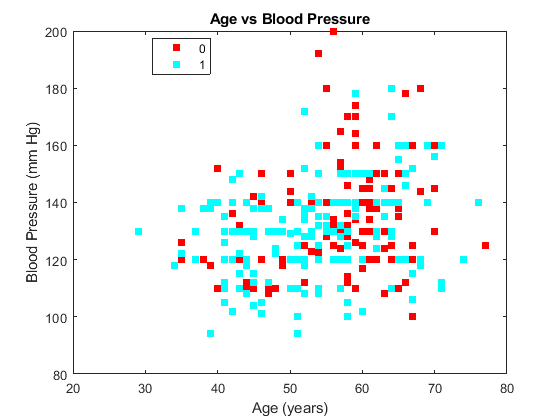

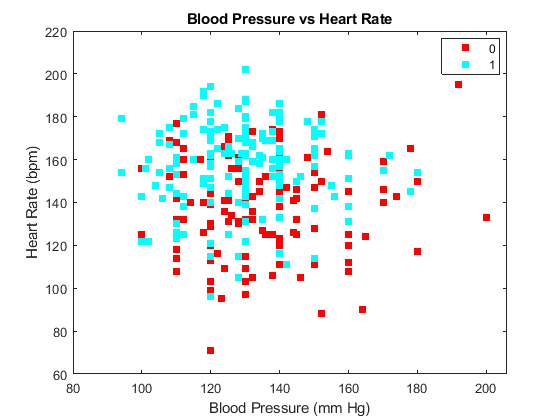

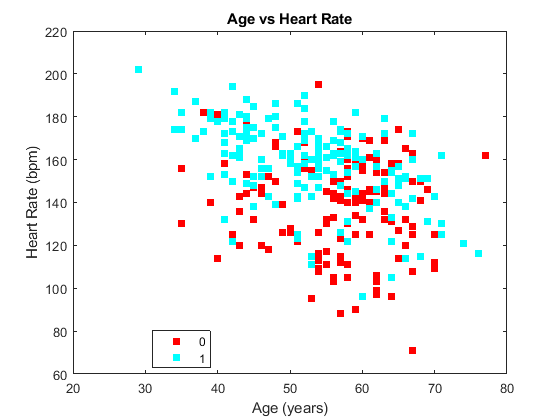

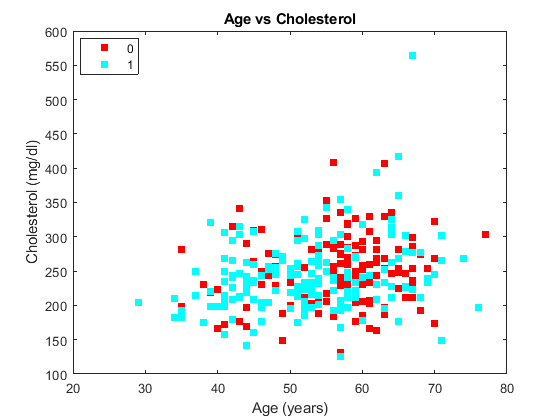

title('Blood Pressure');
subplot(1,4,3);
boxplot(data.age);
title('Age')
subplot(1,4,4);
boxplot(data.chol);

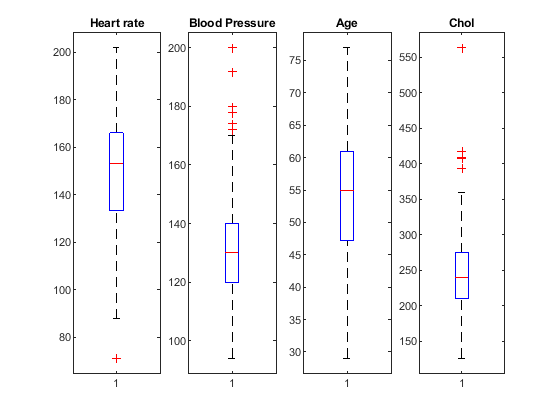

title('Chol')

Machine Learning

%First LDA Model features two parameters: Blood Pressure and Max Heart Rate
% to build the machine learning algorithm.
lda = fitcdiscr(dataset(:,2:3), data.target);
ldaClass = resubPredict(lda);
ldaResubErr = resubLoss(lda);
fprintf("LDA error is %.3f", ldaResubErr);

LDA error is 0.290


%Display of Confusion Matrix of first ML algorithm.
figure(7)
ldaCM = confusionchart(data.target,ldaClass)

ldaCM =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 double]

  Show all properties


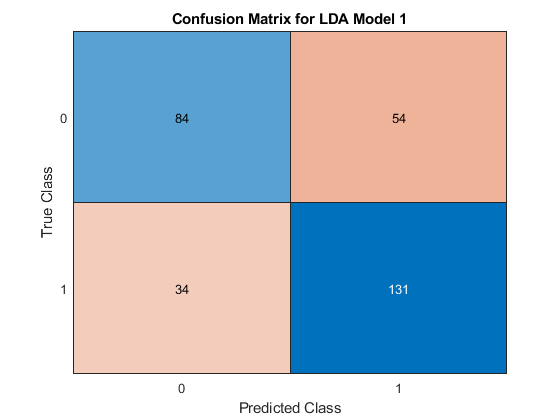

title('Confusion Matrix for LDA Model 1');

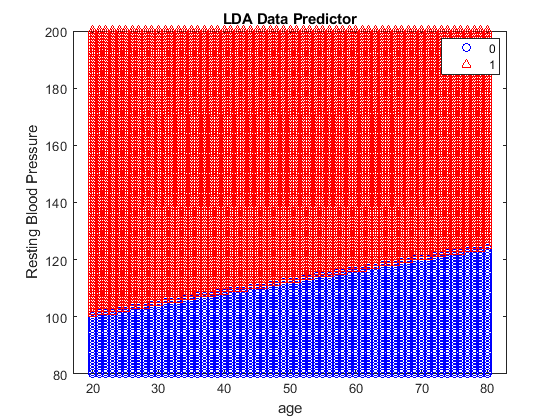

missClsfd = ~(ldaClass == data.target);

%Visualization of how 2D LDA Model charectirized patients based on
%given parameters.
[x,y] = meshgrid(20:1:80, 80:1:200);
x = x(:);
y = y(:);
pred = predict(lda, [x y]);
figure(9)
gscatter(x,y,pred,'br', 'o^');
title('LDA Data Predictor')
xlabel('age')
ylabel('Resting Blood Pressure')


% 9-Dimensional LDA Model tested that shows improved level of accuracy.
ldaAcc = fitcdiscr(dataset, data.target);
ldaClassA = resubPredict(ldaAcc);
ldaResubErrA = resubLoss(ldaAcc);
fprintf("LDA error is %.3f", ldaResubErrA);

LDA error is 0.188


%Confusion Matrix for 9-Dimensional LDA Model.
figure(10)
ldaCMA = confusionchart(data.target,ldaClassA)

ldaCMA =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 double]

  Show all properties


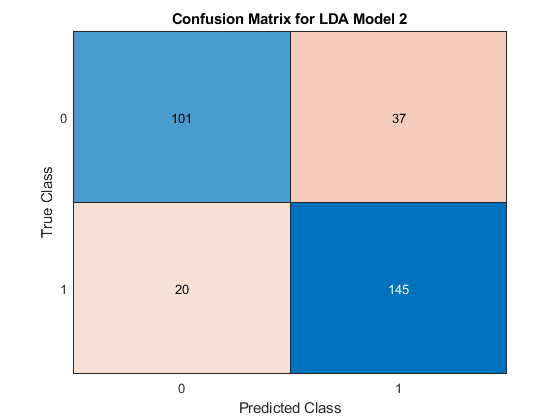

title('Confusion Matrix for LDA Model 2');

missClsfdA = ~(ldaClassA == data.target);



Decision Tree

%Implementation of Decision Tree algorithm using same parameters as 
%previous 9-Dimensional LDA model.
treePred = fitctree(dataset, data.target);
treeClass = resubPredict(treePred);

treeResubErr = resubLoss(treePred);
fprintf("DT error is %.3f", treeResubErr)

DT error is 0.069


%Shows confusion matrix for decision tree model, which is substantially
%more accurate than either of the LDA Models.
figure(11)
treeCM = confusionchart(data.target,treeClass)

treeCM =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 double]

  Show all properties


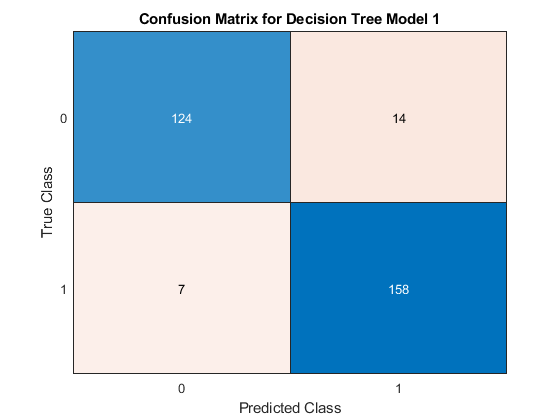

title('Confusion Matrix for Decision Tree Model 1');

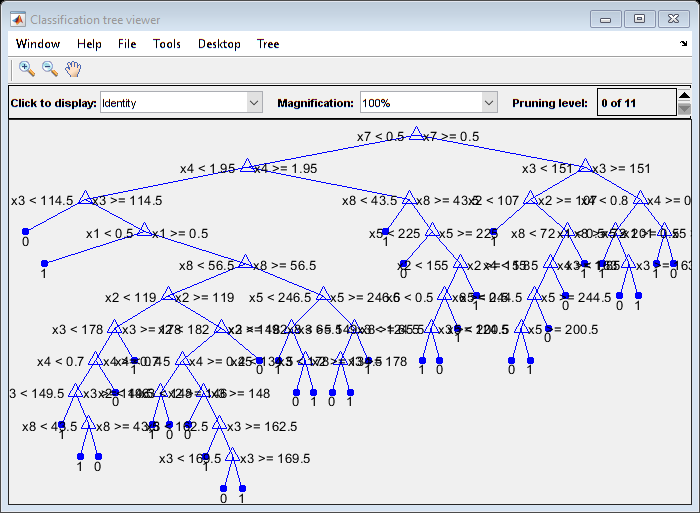



%Visualize how the decision tree used the parameters to decide on whether a
%patient had heart disease present.
view(treePred, 'mode', 'graph')



%Last ML model is a decision tree that uses only a subset of the entire
%dataset to see how data size may affect accuracy.

%The higher accuracy of this model can likely be attributed to the fact
%that the dataset is not as randomized, leading to slightly skewed
%results.
treePred2 = fitctree(dataset(1:200,:), data.target(1:200));
treeClass2 = resubPredict(treePred2);

treeResubErr2 = resubLoss(treePred2);
fprintf("DT error is %.3f", treeResubErr2)

DT error is 0.050


%Visualization of Confusion Matrix, which helps show that this subsection
%of data was likely skewed toward only positive cases.
figure(12)
treeCM2 = confusionchart(data.target(1:200),treeClass2)

treeCM2 =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 double]

  Show all properties


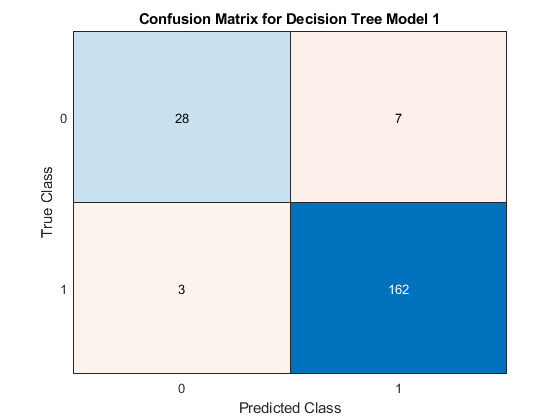

title('Confusion Matrix for Decision Tree Model 1');